# Generating an action potential with NEURON in MATLAB

In this example...

## Initialize the NEURON session

We need to set up our paths so that we can use the NEURON library. Make sure your NEURON path is listed correctly in `setup_nrn_paths.m`, before running it here.

Then, we can start a NEURON session by calling `n = neuron.Neuron()`. To reset the topology created in a previous run of the live script, we call `n.reset_sections()`.

% Initialization & reset.
clear;                  % Clear MATLAB workspace.
setup_nrn_paths;        % Make sure we can find the NEURON library.
n = neuron.Neuron();    % Initialize the NEURON session.
n.reset_sections();     % Reset topology.
n.list_functions();     % Show available top-level variables, functions

Available variables:
    PI
    E
    GAMMA
    DEG
    PHI
    FARADAY
    R
    Avogadro_constant
    hoc_ac_
    float_epsilon
    hoc_cross_x_
    hoc_cross_y_
    default_dll_loaded_
    xopen_broadcast_
    clamp_resist
    celsius
    secondorder
    diam_changed
    nrn_shape_changed_
    nrn_netrec_state_adjust
    nrn_sparse_partrans
    stoprun
    t
    dt
    nseg
    L
    rallbranch
    Ra
    nai0_na_ion
    nao0_na_ion
    ki0_k_ion
    ko0_k_ion
    minf_hh
    hinf_hh
    ninf_hh
    mtau_hh
    htau_hh
    ntau_hh
    usetable_hh
    ib_IntFire4
    eps_IntFire4
    taueps_IntFire4
Available functions (returning a double):
    atan2
    system
    prmat
    solve
    eqinit
    plt
    axis
    plot
    plotx
    ploty
    regraph
    symbols
    printf
    xred
    sred
    ropen
    wopen
    xopen
    hoc_stdout
    chdir
    fprint
    fscan
    sscanf
    sprint
    graph
    graphmode
    fmenu
    lw
    getstr
    strcmp
    setcolor
    startsw
    stopsw
 

                        % and objects.

## Morphology

Axon & branch using `n.Section`.

% Make axon.
axon = n.Section("axon");
axon.nseg = 3;
axon.set_diameter(50);
axon.insert_mechanism("hh");

% Connect branch.
branch = n.Section("branch");
branch.set_diameter(10);
branch.nseg = 4;
branch.length = 1000;
branch.connect(0, axon, 1);
n.topology();

|---|       axon(0-1)
     `---|       branch(0-1)



## Vectors

Tracking time & voltage using `n.Vector`.

% Track time with Vector t_vec.
t_vec = n.Vector();
t = n.ref("t");
t_vec.record(t);

% Track voltage at two points.
v1_vec = n.Vector();
v1 = axon.ref("v", 0.5);
v1_vec.record(v1);
v2_vec = n.Vector();
v2 = branch.ref("v", 1);
v2_vec.record(v2);

## Putting a current clamp on the axon

We can create a current clamp on the axon using `iclamp = n.IClamp(axon, loc)`, where `loc` is a location on the axon between 0 and 1. This is an example of a dynamically generated Neuron Object. Its available attributes and methods can be displayed by calling `iclamp.list_methods()`.

Object properties (`del`, `dur`, `amp`) can be set directly; the value of the current can be monitored at any timestep by calling `iclamp.i`. 

iclamp = n.IClamp(axon, 0); % Insert current clamp at start of axon.
iclamp.list_methods();      % List available attributes and methods of a

Available attributes:
    del
    dur
    amp
    i
Available methods (returning a double):
    loc
    has_loc
    get_loc


                            % dynamically generated Neuron Object.
iclamp.del = 0.5;           % Set delay to 0.5ms.
iclamp.dur = 1;             % Set duration to 1ms.
iclamp.amp = 10;            % Set current amplitude to 10nA.

## Running the simulation

To run the simulation, we call `n.finitialize(voltage)`, and then `n.fadvance()` until the time `n.t` reaches 7 milliseconds.

% Run simulation.
n.finitialize(-65);
while n.t < 7
    if (abs(round(n.t) - n.t) < 1e-6)
        % Print time and current at integer time values (ms)
        fprintf('t (ms): %.4f; I (nA): %.4f \n', n.t, iclamp.i);
    end
    n.fadvance();
end

t (ms): 0.0000; I (nA): 0.0000 
t (ms): 1.0000; I (nA): 10.0000 
t (ms): 2.0000; I (nA): 0.0000 
t (ms): 3.0000; I (nA): 0.0000 
t (ms): 4.0000; I (nA): 0.0000 
t (ms): 5.0000; I (nA): 0.0000 
t (ms): 6.0000; I (nA): 0.0000 


## Plotting an action potential

We can plot using vectors directly.

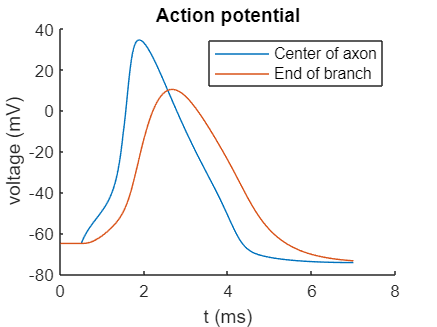

% Plot results.
figure;
hold on;
plot(t_vec, v1_vec);
plot(t_vec, v2_vec);
legend('Center of axon', 'End of branch')
title("Action potential");
xlabel("t (ms)");
ylabel("voltage (mV)");
hold off;